Digital Signal Processing Lab (EE-384L)

# Assignment No. 3:   **Properties of Linear Time-Invariant Systems**

### Reg. No. :   **2016-EE-189**

## Task 1

**Statement:**

Write a MATLAB function $\textrm{get}\_\textrm{system}\_\textrm{out}\left(b,a,x,z\right)$ that implements a CCDE with coefficients b, a, input sequence x and initial conditions vector z. Use your function to implement the following system,


$$y\left\lbrack n\right\rbrack -y\left\lbrack n-1\right\rbrack \;=\;x\left\lbrack n\right\rbrack -x\left\lbrack n-1\right\rbrack +x\left\lbrack n-22050\right\rbrack -x\left\lbrack n-22051\right\rbrack$$


Use voice recorded in previous lab as input (assume first sample of recorded voice is at n = 0, and so on).

**Code (*****get_system_out.m*****):**

Below is the function that computes $y\left\lbrack n\right\rbrack$ (for $0\le n\;<\textrm{len}\left(x\right)$) using CCDE coefficients and initial conditions,


$$y\left\lbrack n\right\rbrack \;=\;-\sum_{k\;=\;1}^N \frac{a_k }{a_0 }y\left\lbrack n-k\right\rbrack +\sum_{k\;=\;0}^M \frac{b_k }{a_0 }x\left\lbrack n-k\right\rbrack$$


% <function>
% computes system output y for 0 <= n < len(x) using CCDE (forward) recurrence formula,
% given b, a, x (for n>=0), and initial conditions (N aux y values, M initial x values).
% assumes x[n] starts at n=0.
%
% <syntax>
% [y, ny] = get_system_out(b, a, x, N_aux, M_init)
%
% <I/O>
% y = filter output { y[-N], y[-N+1], ..., y[-1], y[0], y[1], ..., y[len(x)-1] }
% b = M+1 coefficients { b0, b1, ..., bM } for { x[0], x[-1], ..., x[-M] }
% a = N+1 coefficients { a0, a1, ..., aN } for { y[0], y[-1], ..., y[-N] }
% N_aux = N auxiliary y values { y[-1], y[-2], ...., y[-N] }
% M_init = M initial x values { x[-1], x[-2], ...., x[-M] }

% function [y, ny] = get_system_out(b, a, x, N_aux, M_init)
%     
%     % basic testing of inputs
%     if ~((length(N_aux)+1)==length(a)) 
%         error('Length of "a" should Length of "N_aux" + 1'); 
%     elseif ~((length(M_init)+1)==length(b)) 
%         error('Length of "b" should Length of "M_init" + 1');
%     end
% 
%     % setup y and x for forward recursive computation, and other variables
%     y = [wrev(N_aux) zeros(1, length(x))];
%     x2 = [wrev(M_init) x];
%     N = length(N_aux);
%     M = length(M_init);
%     ny = -N:length(x)-1;
%     
%     % starting indexes for x and y -> x[0] and y[0]
%     ix = N + 1;
%     iy = M + 1;
%     
%     % compute y[n] for n=0 to n=len(x)-1 
%     for i = 0:length(x)-1
%         
%         % (mult. with bM:b0 and) sum n-M to n-0 values of x (here, n=ix)
%         x_sum = x2(ix-M:ix) * wrev(b)';
%         
%         % (mult. with aN:a1 and) sum n-N to n-1 values of y (here, n=iy)
%         y_sum = y(iy-N:iy-1) * wrev(a(2:end));
%         
%         % compute current y value (at n=iy) (here, a(1) = a0)
%         y(iy) = (-y_sum + x_sum) / a(1);
%         
%         ix = ix + 1;
%         iy = iy + 1;
%     end
% end

**Implementing given system using previously recorded input:**

For the given system, assuming $x\left\lbrack n\right\rbrack$ starts at $n=0$, the input parameters to the $\textrm{get}\_\textrm{output}\_\textrm{system}$ will be,


$$\begin{array}{l}
x\;=\;\textrm{recorded}\;\textrm{input}\\
b\;=\;\left\lbrace b_0 \;,b_1 \;,\ldotp \ldotp \ldotp ,b_{22050} \;,b_{22051} \right\rbrace \;=\;\left\lbrace 1,-1,0,0,\ldotp \ldotp \ldotp ,0,0,1,-1\right\rbrace \\
a\;=\;\left\lbrace a_0 \;,a_1 \right\rbrace \;=\;\left\lbrace 1,-1\right\rbrace \\
N\_\textrm{aux}\;=\;\left\lbrace y\left\lbrack -1\right\rbrack \right\rbrace \;=\;\left\lbrace 0\right\rbrace \\
M\_\textrm{init}\;=\;\left\lbrace x\left\lbrack -1\right\rbrack ,\;\ldotp \ldotp \ldotp ,x\left\lbrack -22050\right\rbrack ,x\left\lbrack -22051\right\rbrack \right\rbrace \;=\;\left\lbrace 0,0,\ldotp \ldotp \ldotp ,0,0\right\rbrace 
\end{array}$$


Since the system is LTI Causal, its auxiliary conditions are "*initial rest conditions*", and since $x\left\lbrack n\right\rbrack =0$ for $n<0$, hence $y\left\lbrack n\right\rbrack$ will be $0$ for $n<0$, i.e. $y\left\lbrack -1\right\rbrack =0$, $y\left\lbrack -2\right\rbrack =0$ and so on. 

**Code (with results):**

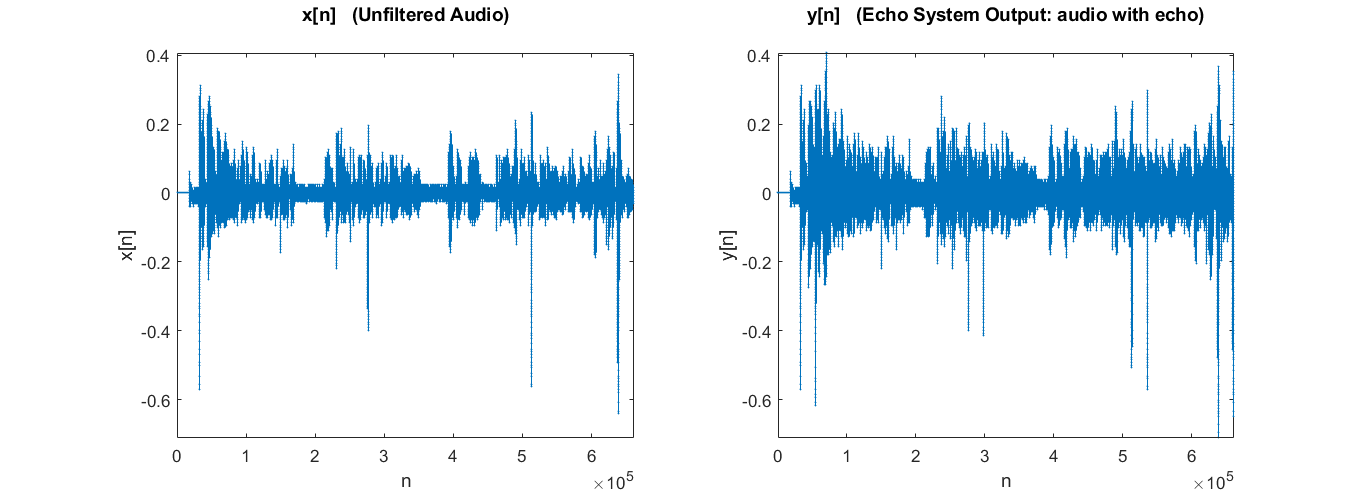

% task: implement echo system, for input = lab-2 voice rec. (15s), using get_system_out()

% read audio data from lab2.wav file (x[n]=0 for n<0)
[x, Fs] = audioread('lab2.wav');

% convert x to single-channel audio (mono) to use echo filter
x = x(:,1)';

% initialize variables corresponding to CCDE of echo system (LTI Causal)
b = [1 -1 zeros(1, 22050-2) 1 -1];         % = { b0, b1, ..., b22050, b22051 }
a = [1, -1];                               % = { a0, a1 }
N_aux = [0];                               % = { y[-1] }
M_init = zeros(1, 22051);                  % = { x[-1], x[-2], ..., x[-22050], x[-22051] }

% compute y[n] for 0 <= n < length(x)
[y, ny] = get_system_out(b, a, x, N_aux, M_init);
save("lab3_y.mat",'y', 'ny');

% plot x[n] and y[n]
fig = figure; 
set(fig,'Units','normalized','Position',[0 0 1.4 .9]);  

% plot x[n]
subplot(1, 2, 1);
stem(x, 'filled', 'MarkerSize', 1);
xlabel('n'); ylabel('x[n]'); 
xlim([0 length(x)]); ylim([min(y) max(y)]); 
ax = gca; ax.FontSize = 13;
title({'x[n]   (Unfiltered Audio)';''}, 'FontSize', 14);

% plot y[n]
subplot(1, 2, 2);
stem(ny, y, 'filled', 'MarkerSize', 1);
xlabel('n'); ylabel('y[n]'); 
xlim([0 max(ny)]); ylim([min(y) max(y)]); 
ax = gca; ax.FontSize = 13;
title({'y[n]   (Echo System Output: audio with echo)';''}, 'FontSize', 14);

% get and play echo-signal y(t) using sound command
sound(y, Fs);

The echo-signal $y\left\lbrack n\right\rbrack$, generated here using the echo system's CCDE and the $\textrm{get}\_\textrm{output}\_\textrm{system}$ function, matches exactly with the signal generated using the system equation provided in previous lab. This is verified from the $y\left\lbrack n\right\rbrack$ plot (right) in the figure above, as well as from the playback sound. 

Hence, the DT system with the equation $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -x\left\lbrack n-22050\right\rbrack$ has been successfully implemented here by using its CCDE.

**Question (1):**

Since the system we implemented last time was an LTI causal system, which initial conditions would you use to implement the CCDE.

**Answer (1):**

Since the system is LTI Causal, its auxiliary conditions are "*initial rest conditions*", and since $x\left\lbrack n\right\rbrack =0$ for $n<0$, hence $y\left\lbrack n\right\rbrack$ will be $0$ for $n<0$, i.e. $y\left\lbrack -1\right\rbrack =0$, $y\left\lbrack -2\right\rbrack =0$ and so on. 

Further detail of the inputs (coefficients and initial conditions) provided to the $\textrm{get}\_\textrm{output}\_\textrm{system}$ function have been discussed in the implementation section above.

**Question (2):**

Now suppose the initial conditions are $y\left\lbrack -1\right\rbrack =3$. Is this a linear system? Why or why not? Choose a suitable input and show the output using your function to justify your answer.

**Answer (2):**

For linearity, a system must satisfy both *Homogeneity* and *Superposition*. To test the new system's linearity, it is first implemented using the CCDE and $y\left\lbrack -1\right\rbrack =3$, and then two different inputs $x_1$ and $x_2$ can be used to test if the system satisfies combined homogeneity and superposition, that is, whether,


$${A\;y}_1 +B\;y_2 \;\;\;=\;{\;\;y}_3 \;\;\;=\;\;\;T\left\lbrack {A\;x}_1 +B\;x_2 \right\rbrack$$


where A and B are scalar, and $y_1 =T\left\lbrack x_1 \right\rbrack$ & $y_2 =T\left\lbrack x_2 \right\rbrack$.

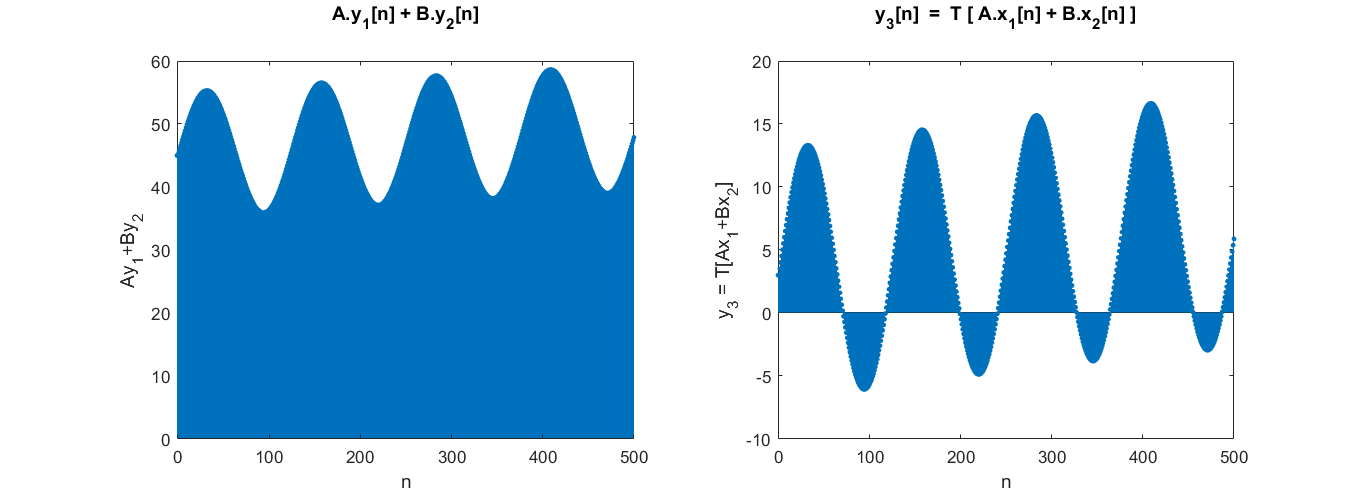

% initialize variables corresponding to CCDE of new system (with y[-1]=3)
b = [1 -1 zeros(1, 22050-2) 1 -1];         % = { b0, b1, ..., b22050, b22051 }
a = [1, -1];                               % = { a0, a1 }
N_aux = [3];                               % = { y[-1] }
M_init = zeros(1, 22051);                  % = { x[-1], x[-2], ..., x[-22050], x[-22051] }

% initialize two inputs x1[n] & x2[n], and A & B
nx = 0:500;
x1 = sin(.002*nx);
x2 = sin(.05*nx);
A = 5;
B = 10;

% compute A.y1[n]+B.y2[n]
[y1, ny1] = get_system_out(b, a, x1, N_aux, M_init);
[y2, ny2] = get_system_out(b, a, x2, N_aux, M_init);
a_y1_plus_b_y2 = A*y1 + B*y2;

% compute y3[n] = T[A.x1[n]+B.x2[n]]
x3 = A*x1 + B*x2;
[y3, ny3] = get_system_out(b, a, x3, N_aux, M_init);

% plot A.y1[n]+B.y2[n] and y3[n] = T[A.x1[n]+B.x2[n]]
fig = figure; set(fig,'Units','normalized','Position',[0 0 1.4 .9]); 

% plot A.y1[n]+B.y2[n]
subplot(1, 2, 1);
stem(ny1, a_y1_plus_b_y2, 'filled', 'MarkerSize', 3);
xlabel('n'); ylabel('Ay_1+By_2'); 
xlim([min(ny1) max(ny1)]); ax = gca; ax.FontSize = 13;
title({'A.y_1[n] + B.y_2[n]';''}, 'FontSize', 14);

% plot y3[n] = T[A.x1[n]+B.x2[n]]
subplot(1, 2, 2);
stem(ny3, y3, 'filled', 'MarkerSize', 3);
xlabel('n'); ylabel('y_3 = T[Ax_1+Bx_2]'); 
xlim([min(ny3) max(ny3)]); ax = gca; ax.FontSize = 13;
title({'y_3[n]  =  T [ A.x_1[n] + B.x_2[n] ]';''}, 'FontSize', 14);

% numerically comparing outputs A.y1[n]+B.y2[n] and y3[n] = T[A.x1[n]+B.x2[n]]
isequal(a_y1_plus_b_y2, y3)                % returns 0 if not equal

ans = logical
   0


As can be seen from the above plots, and the numerical comparison, the system does not satisfy the *homogeneity+superposition* condition for linearity, since the results for ${\textrm{Ay}}_1 +By_2$ and $y_3 =T\left\lbrack {\textrm{Ax}}_1 +Bx_2 \right\rbrack$ are not the same. Hence, for the initial conditions $y\left\lbrack -1\right\rbrack =3$, the system is **non-linear**.

Here, if $N\_\textrm{aux}$ had been set to the previous (rest condition, LTI Causal system) value i.e. $\left\lbrack 0\right\rbrack ;$ then the results of linearity test would match.

**Question (3):**

Plot the impulse response of the system for y[−1] = 0.

**Answer (3):**

For impulse response, the following input is given to the LTI system,


$$x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack$$


where $\delta \left\lbrack n\right\rbrack$ is $1$ for $n=0$ and $0$ for $n\not= 0$.

% reset initial conditions to rest for LTI Causal system (i.e. y[-1]=0)
N_aux = [0];                               % = { y[-1] }

% initialize input x[n] = delta[n]
n = 0:22050*3;
delta = [1 zeros(1, length(n)-1)];         % = 1 only for n=0

% compute y[n]=h[n] (impulse response) of system for 0 <= n < length(x)
[h, nh] = get_system_out(b, a, delta, N_aux, M_init);

% plot impulse response h[n] of system

*(Figure is on the next page.)*

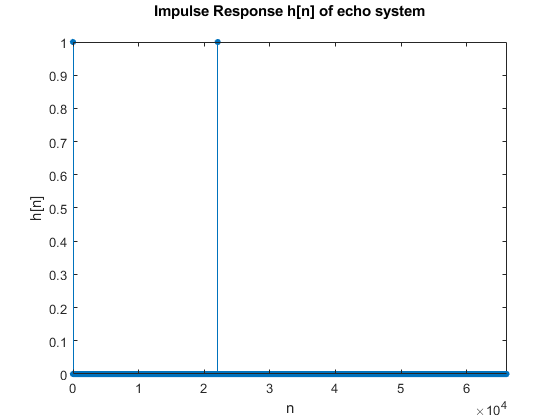

fig = figure;
stem(nh, h, 'filled', 'MarkerSize', 4);
xlabel('n'); ylabel('h[n]'); 
xlim([0 length(delta)]);
title({'Impulse Response h[n] of echo system';''});

This impulse response $h\left\lbrack n\right\rbrack$, found using CCDE of system, can be verified by comparing it with the impulse response found using the system equation $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -x\left\lbrack n-22050\right\rbrack$, which gives,


$$h\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack -\delta \left\lbrack n-22050\right\rbrack$$


This matches with the impulse reponse found using CCDE (shown in figure above).

*Task 2 starts from the next page.*

## Task 2

**Statement:**

Consider an LTI system with the following impulse response: 


$$h\left\lbrack n\right\rbrack =u\left\lbrack n\right\rbrack -u\left\lbrack n-5\right\rbrack$$


Plot its frequency response using MATLAB (using set of and $\omega$ values, i.e. numerically, not by analyzing expression and plotting it).

**Methodology:**

For a system with impulse response $h\left\lbrack n\right\rbrack$, its frequency response $H\left(e^{\textrm{jw}} \right)$ is given by,


$$H\left(e^{\textrm{jw}} \right)=\sum_{k\;=\;-\infty }^{\infty } h\left\lbrack k\right\rbrack \;e^{-\textrm{jwk}}$$


which is periodic with period $2\pi$. 

Given $h\left\lbrack n\right\rbrack$ is $0$ for all values of $n$ except $0\le n<5$ (where it is $1$), hence its frequency response is given by,


$$H\left(e^{\textrm{jw}} \right)=\sum_{k\;=\;0}^{k\;=\;4} \left(1\right)\;e^{-\textrm{jwk}}$$


The following code uses matrix-manipulation on vectors of $h\left\lbrack n\right\rbrack$, $n$, and frequency $\omega$ to implement this summation.

**Code (with results):**

% initialize variables for the rectangular pulse h[n]
n = 0:4;                                   % define vector n from 0 to 4
h = ones(1, length(n));                    % h[n] = [1, 1, 1, 1, 1] (for n=0:4)

% initialize variables for computing freq. resp. of h[n]
w = -2*pi:0.01:2*pi;

% compute freq. resp. of h[n] using stated equation 
% with help of matrix-multiplication on the vectors h, n, and w
Hw = h * exp(-1i * n' * w);

% obtain magnitude and phase of freq. resp. H(w)
Hw_mag = abs(Hw);                          % get the magnitude of H(w)
Hw_ang = angle(Hw)*180/pi;                 % get the phase (angle) of H(w) in degrees
                                                
% obtain real and imaginary parts of freq. resp. H(w)
Hw_real = real(Hw);                        % get the real part of H(w)
Hw_imag = imag(Hw);                        % get the imaginary part of H(w)
                                                
% plot magnitude and phase of freq. resp. H(w), 
% and also its real and imaginary parts

*(Figure is on the next page.)*

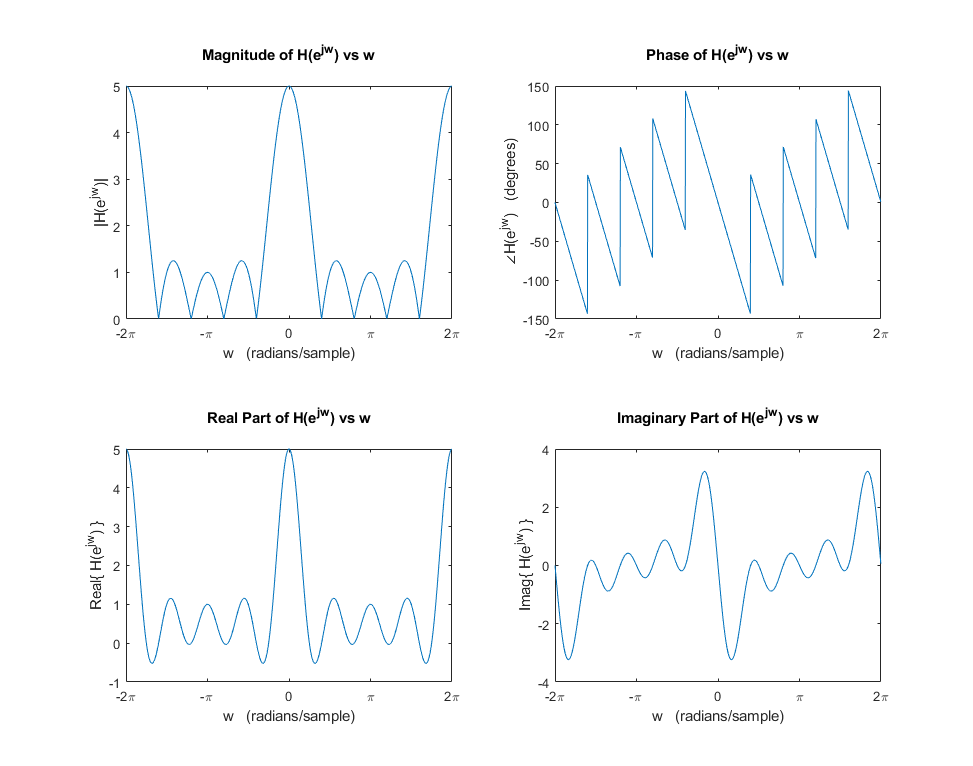

fig = figure; set(fig,'Units','normalized','Position',[0 0 1 1.4]); 

% plot magnitude of H(w) vs w
subplot(2, 2, 1);
plot(w, Hw_mag);
xlabel('w   (radians/sample)');
ylabel('|H(e^{jw})|');
title({'Magnitude of H(e^{jw}) vs w';''});
setDTFTradialAxis()

% plot phase of H(w) vs w
subplot(2, 2, 2);
plot(w, Hw_ang);
xlabel('w   (radians/sample)');
ylabel('∠H(e^{jw})   (degrees)');
title({'Phase of H(e^{jw}) vs w';''});
setDTFTradialAxis()

% plot real part of H(w) vs w
subplot(2, 2, 3);
plot(w, Hw_real);
xlabel('w   (radians/sample)');
ylabel('Real\{ H(e^{jw}) \}');
title({'';'Real Part of H(e^{jw}) vs w';''});
setDTFTradialAxis()

% plot imaginary part of H(w) vs w
subplot(2, 2, 4);
plot(w, Hw_imag);
xlabel('w   (radians/sample)');
ylabel('Imag\{ H(e^{jw}) \}');
title({'';'Imaginary Part of H(e^{jw}) vs w';''});
setDTFTradialAxis()

**Question (1):**

Calculate the frequency response of the system on paper. Plot the resulting expression. Is the plot similar to the one you obtained using MATLAB?

**Answer (1):**

The work done on paper (derivation of frequency response equations and hand-plot of magnitude and phase) has been attached starting at the next page.

*The work done on paper starts from the next page.*

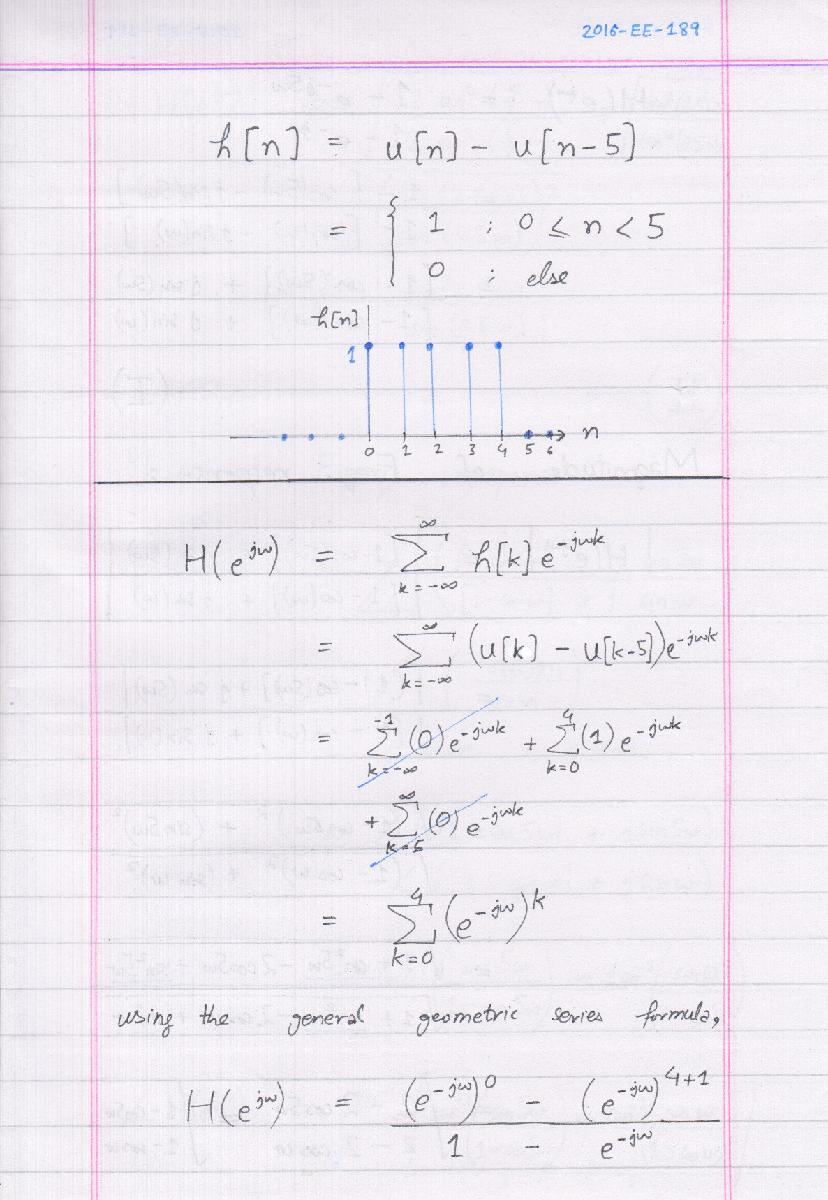

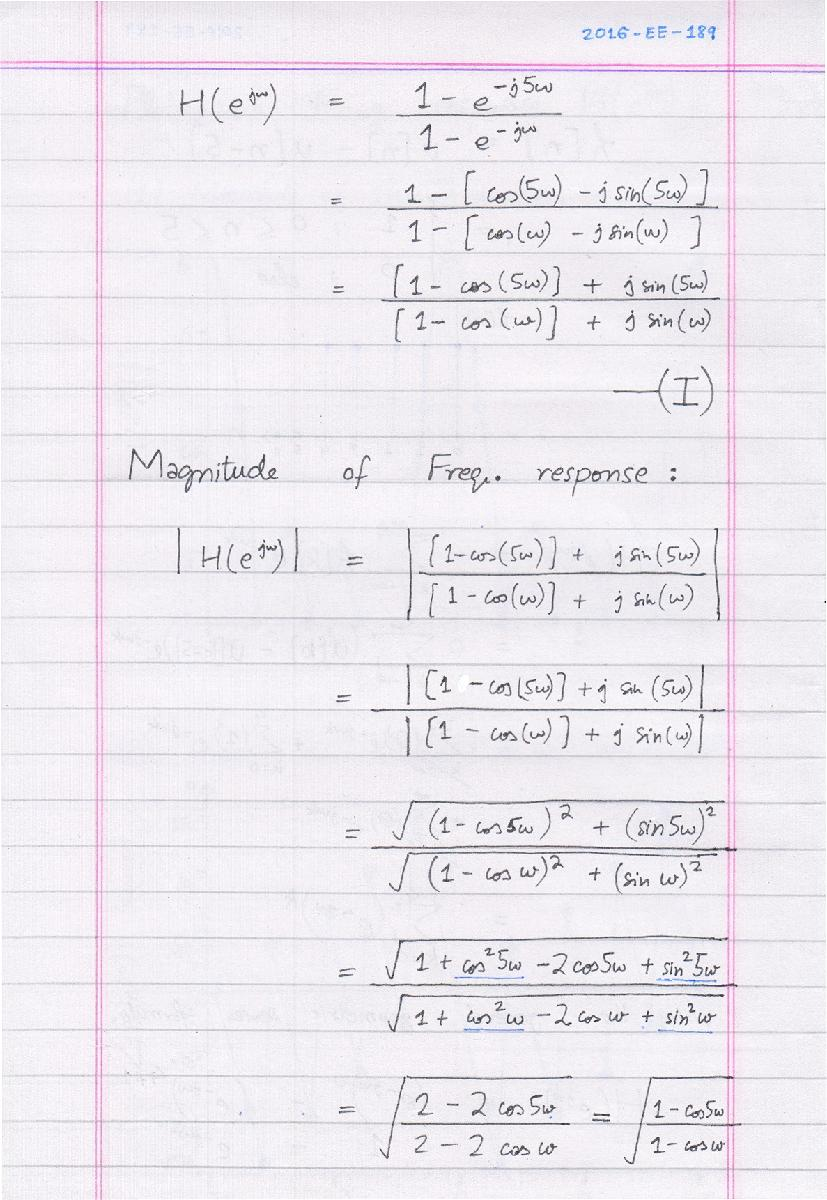

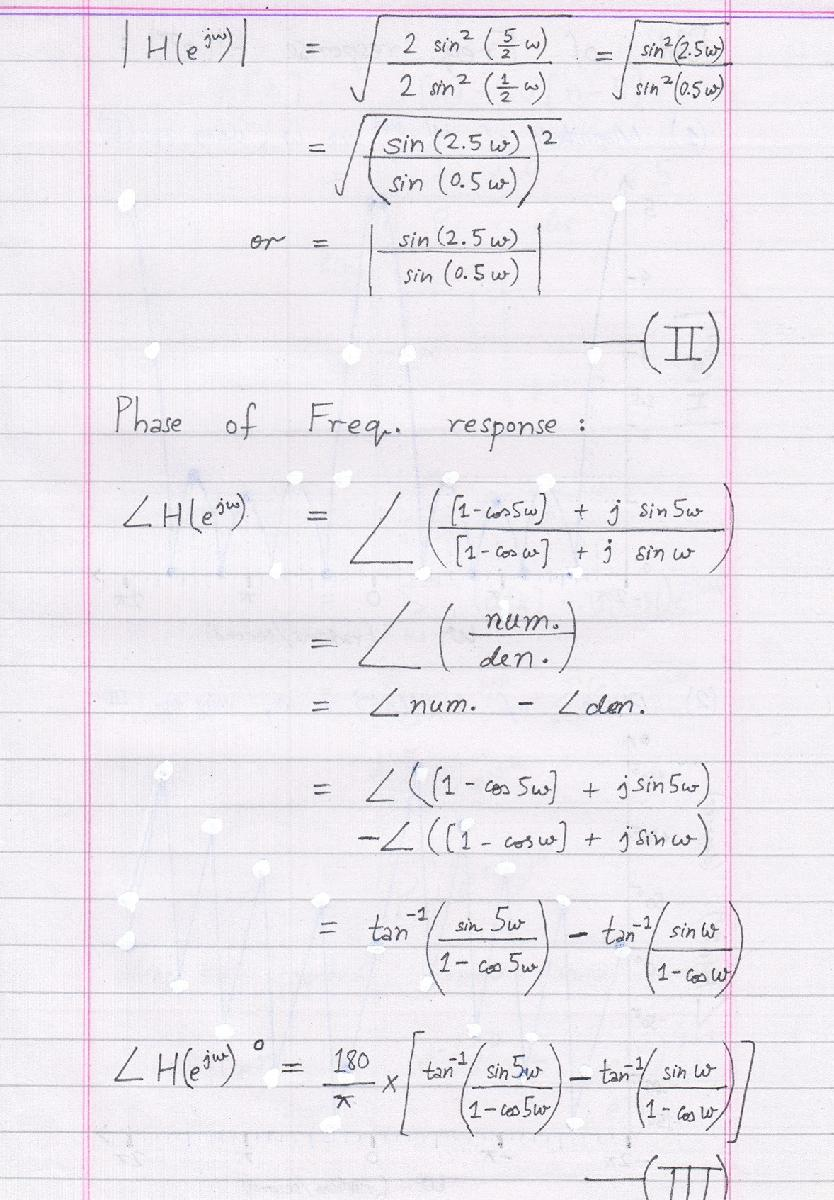

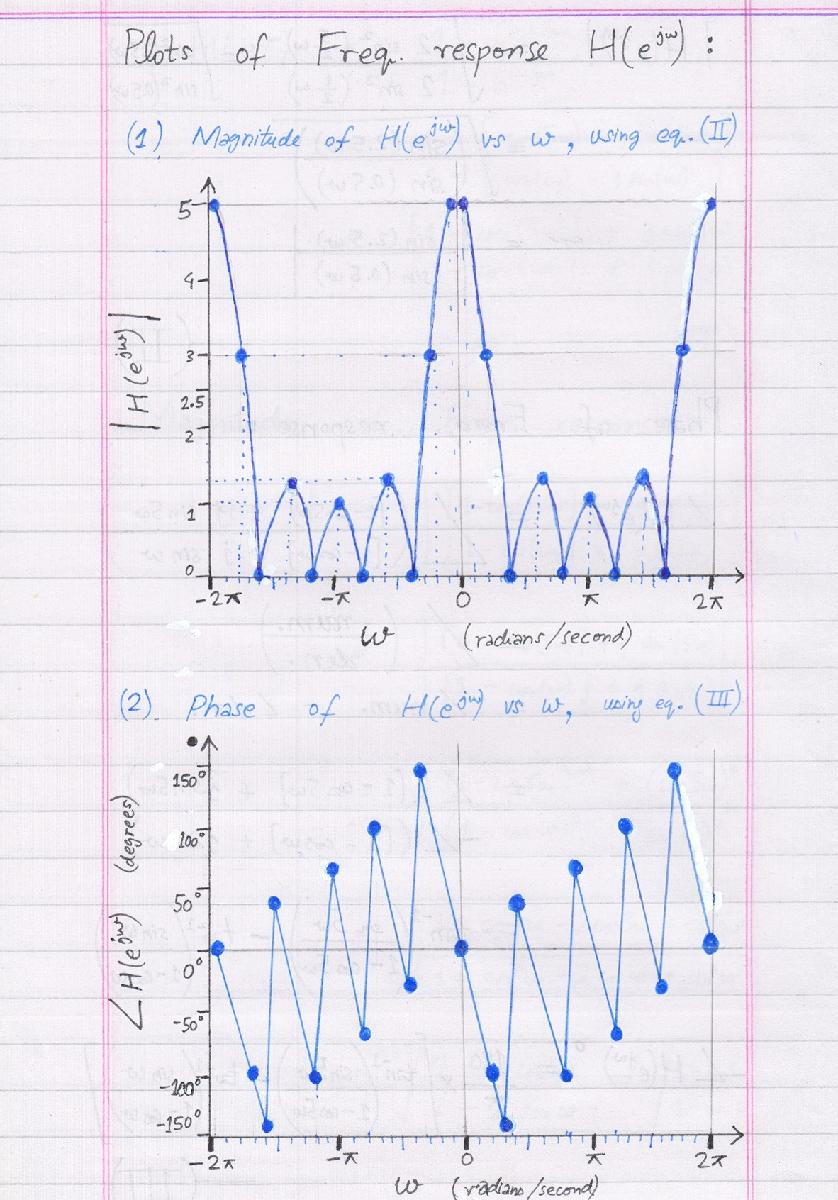

Hence, the hand-made plots (using derived frequency response equations) match with the MATLAB (numerically-computed) plots of magnitude and phase of the frequency response. 

For verification, these plots of derived magnitude and phase equations, have also been plotted in MATLAB (using the equations), with the code given below.

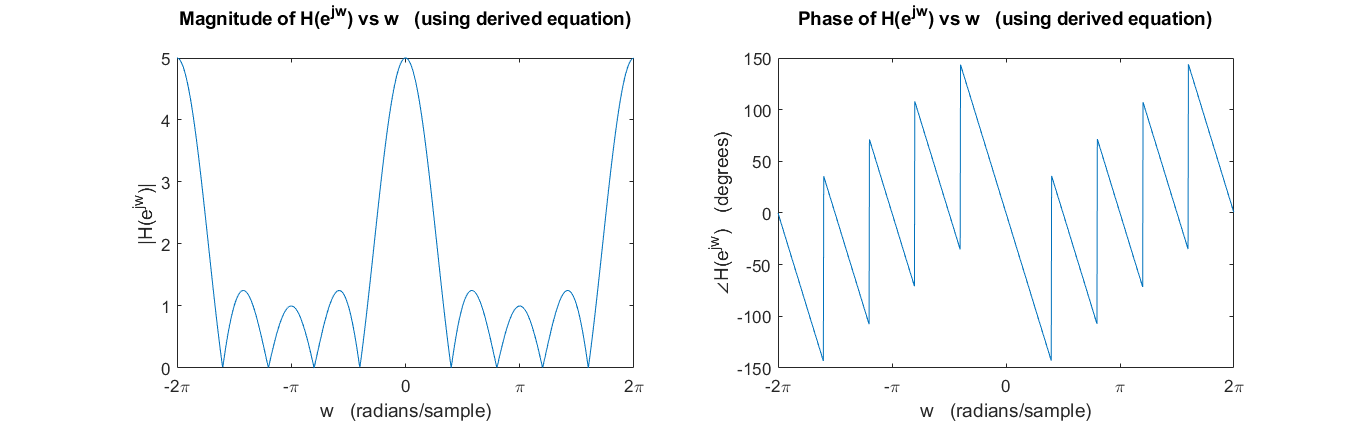

% initialize frequency vector for freq. resp. of h[n]
w = -2*pi:0.01:2*pi;
  
% compute magnitude of freq. resp. |H(w)| using derived equation
Hw_mag_EQ = sqrt((sin(2.5*w) ./ sin(0.5*w)).^2);    % to keep values positive

% compute phase of freq. resp. ∠H(w) using derived equation
Hw_ang_EQ = atan2(sin(5*w),(1-cos(5*w))) - atan2(sin(w),(1-cos(w)));
Hw_ang_EQ = Hw_ang_EQ*180/pi;                       % convert to degrees

% plot magnitude and phase of freq. resp. H(w), found using derived equations
fig = figure; set(fig,'Units','normalized','Position',[0 0 1 .]); 

% plot magnitude of H(w) vs w
subplot(1, 2, 1);
plot(w, Hw_mag_EQ);
xlabel('w   (radians/sample)');
ylabel('|H(e^{jw})|');
ax = gca; ax.FontSize = 13;
title({'Magnitude of H(e^{jw}) vs w   (using derived equation)';''}, 'FontSize', 14);
setDTFTradialAxis()

% plot phase of H(w) vs w
subplot(1, 2, 2);
plot(w, Hw_ang_EQ);
xlabel('w   (radians/sample)');
ylabel('∠H(e^{jw})   (degrees)');
ax = gca; ax.FontSize = 13;
title({'Phase of H(e^{jw}) vs w   (using derived equation)';''}, 'FontSize', 14);
setDTFTradialAxis()